#### AERO50003

#### Introduction to Numerical Methods for ODEs and PDEs

### **Tutorial Sheet 3**

## Systems of ODEs & Boundary Value Problems

Masoud Seifikar

Autumn Term 2023

Department of Aeronautics, Imperial College London 

#### Exercise 1 (Pendulum) 

The motion of a simple pendulum is described by the differential equation 

d^2 θ / dt^2 + g / l * sin(θ) = 0 ,

where g = 9.81 is the gravitational constant, l = 0.1 is the length of the pendulum and θ is the angle of the pendulum with respect to the vertical axis. We wish to obtain a numerical solution for the interval t ∈ [0, 5]. Suppose the pendulum has an intial angle θ(0) = 1 and an initial angular velocity θ ′ (0) = 0.

1. Write the above second order ODE as a system of (two) first order ODEs.

% y1 = θ, y2 = θ'
% y1' = y2, y2' =  -g / l * sin(θ)
% y' = [y2; -g / l * sin(y1)] , y(0) = [1; 0]

2. Use explicit Euler with stepsize h = 0.01 to obtain a numerical solution of the ODE. Comment on the resulting numerical solution.

3. Use 4th-order Runge-Kutta with stepsizes h = 0.1 and h = 0.05 to obtain numerical solutions of the ODE. Comment on the resulting numerical solutions.

4. Obtain and plot a numerical solution using MATLAB’s built-in function ”ode45” with the default tolerance options. 

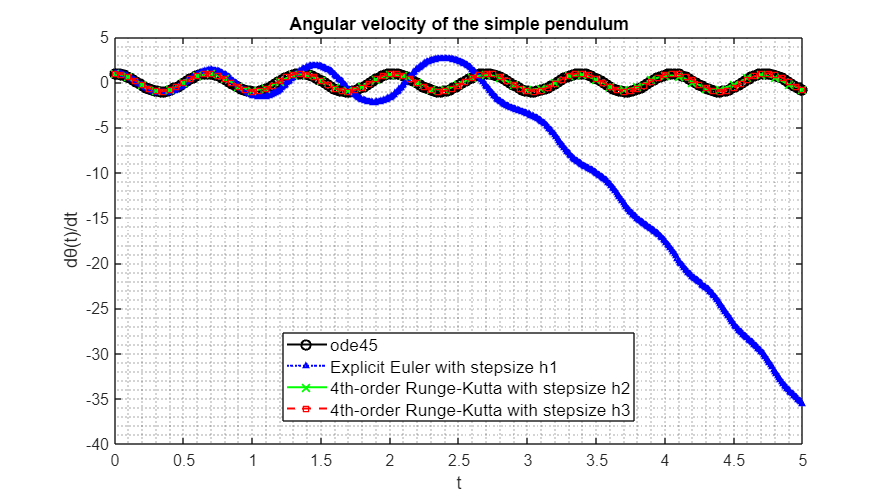

% Housekeeping
clear
clc
close all

% Define the basic parameters
y0 = [1; 0]; % define the initial condition
t0 = 0;      % define the initial time
tf = 5;      % define the final time

h1 = 0.01; % define the stepsize h1
h2 = 0.1;  % define the stepsize h2
h3 = 0.05; % define the stepsize h3

g = 9.81; % gravitational constant
l = 0.1;  % length of the pendulum

% Define the function
f = @(t, y) [y(2); -(g/l)*sin(y(1))];

% Compute the numerical solution
[t1, y1] = ExplicitEuler(f, t0, tf, y0, h1);
[t2, y2] = RungeKutta4(f, t0, tf, y0, h2);
[t3, y3] = RungeKutta4(f, t0, tf, y0, h3);

% Using built-in function solve the numerical solutions
[t4, y4] = ode45(f, [t0 tf], y0);
t4 = t4';
y4 = y4';

% Plot the numerical solutions for angular velocity
plot(t4, y4(1, :), '-ok', LineWidth = 1.5, MarkerSize = 7);  % plot ode45
hold on
plot(t1, y1(1, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Explicit Euler with stepsize h1
hold on
plot(t2, y2(1, :), '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot 4th-order Runge-Kutta with stepsize h2
hold on
plot(t3, y3(1, :), '--sr', LineWidth = 1.5, MarkerSize = 5); % plot 4th-order Runge-Kutta with stepsize h3
hold off

title('Angular velocity of the simple pendulum', FontSize = 15);
legend('ode45', 'Explicit Euler with stepsize h1', '4th-order Runge-Kutta with stepsize h2', ...
    '4th-order Runge-Kutta with stepsize h3', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('dθ(t)/dt');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph
set(gcf, 'Position', [0 0 1920 1080]); % show plot with larger size

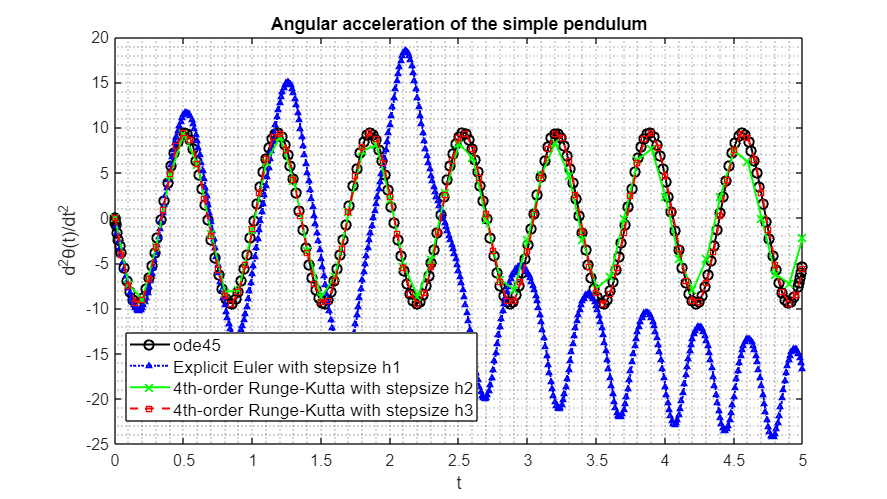

% Plot the numerical solutions for angular acceleration
plot(t4, y4(2, :), '-ok', LineWidth = 1.5, MarkerSize = 7);  % plot ode45
hold on
plot(t1, y1(2, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Explicit Euler with stepsize h1
hold on
plot(t2, y2(2, :), '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot 4th-order Runge-Kutta with stepsize h2
hold on
plot(t3, y3(2, :), '--sr', LineWidth = 1.5, MarkerSize = 5); % plot 4th-order Runge-Kutta with stepsize h3
hold off

title('Angular acceleration of the simple pendulum', FontSize = 15);
legend('ode45', 'Explicit Euler with stepsize h1', '4th-order Runge-Kutta with stepsize h2', ...
    '4th-order Runge-Kutta with stepsize h3', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('d^2θ(t)/dt^2');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

#### Exercise 2 (Simple harmonic oscilaltor) 

Consider the simple harmonic oscillator 

y′ = [0 1; −1 0] y = Ay .

In Tutorial Sheet 1 we saw that the system of ODEs can be converted, via a change of coordiantes, to two uncoupled scalar ODEs. In this exercise we wish to solve the system of ODEs directly (without performing any change of coordinates). Let y(0) = [10; 1] . 

1. Attempt to obtain a numerical solution using explicit Euler with stepsize h = 0.1. What do you observe and why? 

2. Use 4th-order Runge-Kutta with stepsize h = 0.1 to obtain a numerical solution of the system of ODEs. 

3. Use the trapezoidal method (together with the inbuilt MATLAB function “fsolve”) with stepsize h = 0.1 to obtain a numerical solution of the system of ODEs. 

% Housekeeping
clear
clc
close all

% Define the basic parameters
y0 = [10; 1]; % define the initial condition
t0 = 0;       % define the initial time
tf = 50;      % define the final time

h = 0.1; % define the stepsize

% Define the function
f = @(t, y) [y(2); -(y(1))];

% Compute the numerical solution
[t1, y1] = ExplicitEuler(f, t0, tf, y0, h);
[t2, y2] = RungeKutta4(f, t0, tf, y0, h);
[t3, y3] = Trapezoidal(f, t0, tf, y0, h);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

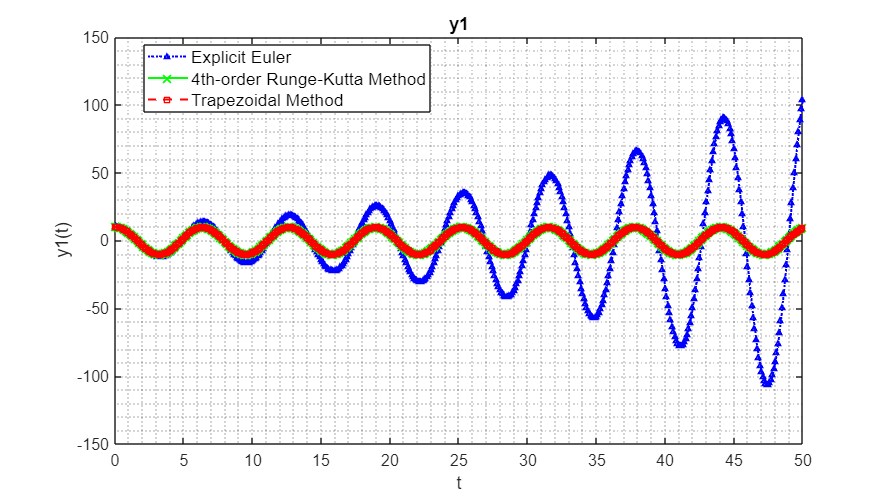


% Plot the numerical solutions for y1
plot(t1, y1(1, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Explicit Euler with stepsize h1
hold on
plot(t2, y2(1, :), '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot 4th-order Runge-Kutta with stepsize h2
hold on
plot(t3, y3(1, :), '--sr', LineWidth = 1.5, MarkerSize = 5); % plot Trapezoidal Method with stepsize h3
hold off

title('y1', FontSize = 15);
legend('Explicit Euler', '4th-order Runge-Kutta Method', ...
    'Trapezoidal Method', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y1(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph
set(gcf, 'Position', [0 0 1920 1080]); % show plot with larger size

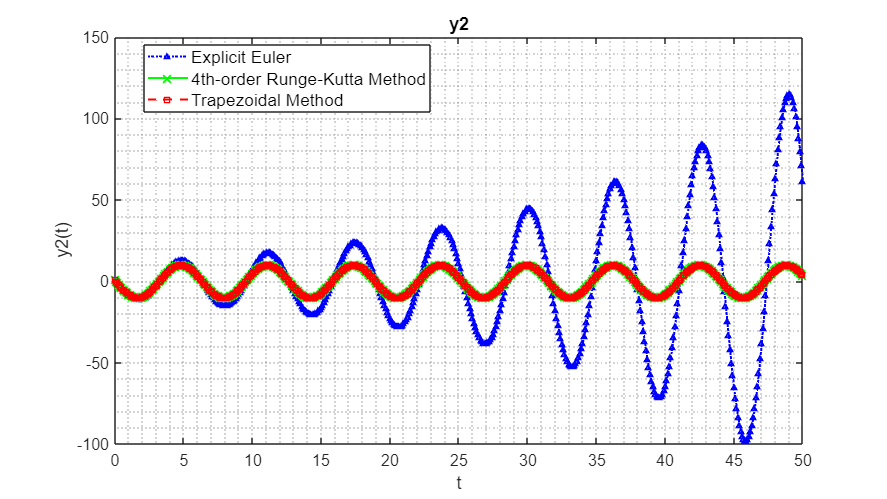

% Plot the numerical solutions for y2
plot(t1, y1(2, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Explicit Euler with stepsize h1
hold on
plot(t2, y2(2, :), '-xg', LineWidth = 1.5, MarkerSize = 8);  % plot 4th-order Runge-Kutta with stepsize h2
hold on
plot(t3, y3(2, :), '--sr', LineWidth = 1.5, MarkerSize = 5); % plot Trapezoidal Method with stepsize h3
hold off

title('y2', FontSize = 15);
legend('Explicit Euler', '4th-order Runge-Kutta Method', ...
    'Trapezoidal Method', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('y2(t)');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

4. How do 4th-order Runge-Kutta and the trapezoidal method compare?

% Very close.

#### Exercise 3 (The van der Pol equation - a stiff system) 

The ODE 

x′′ = −µ( 1 − x^2 )x ′ + x = 0 ,

where µ > 0 is a scalar parameter, is the so-called van der Pol equation. Suppose x(0) = 2 and x ′ (0) = 0. We wish to obtain a numerical solution for the time interval t ∈ [0, 50]. 

1. Write the second order ODE as a system of first order ODEs. 

% y1 = x, y2 = x'
% y1' = y2, v' =  -y1 + µ * (1 - y1 ^ 2) * y2
% y' = [y2; -y1 + µ * (1 - y1 ^ 2) * y2] , y(0) = [2, 0]

2. Let µ = 1 and obtain a numerical solution to the ODE using explicit Euler with stepsize h = 0.01. 

3. Again, letting µ = 1, obtain a numerical solution using MATLAB’s builti-in function ”ode45”. 

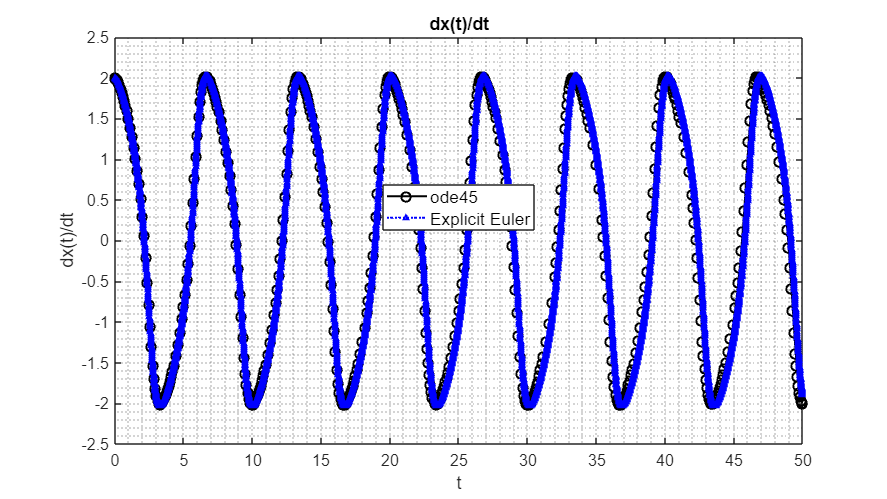

% Housekeeping
clear
clc
close all

% Define the basic parameters
y0 = [2; 0]; % define the initial condition
t0 = 0;      % define the initial time
tf = 50;     % define the final time

h = 0.01; % define the stepsize h

Mu = 1; % scalar parameter

% Define the function
f = @(t, y) [y(2); -y(1) + Mu * (1 - y(1) ^ 2) * y(2)];

% Compute the numerical solution
[t1, y1] = ExplicitEuler(f, t0, tf, y0, h);

% Using built-in function solve the numerical solutions
[t2, y2] = ode45(f, [t0 tf], y0);
t2 = t2';
y2 = y2';

% Plot the numerical solutions for x'
plot(t2, y2(1, :), '-ok', LineWidth = 1.5, MarkerSize = 7);  % plot ode45
hold on
plot(t1, y1(1, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Explicit Euler
hold off

title('dx(t)/dt', FontSize = 15);
legend('ode45', 'Explicit Euler', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('dx(t)/dt');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph
set(gcf, 'Position', [0 0 1920 1080]); % show plot with larger size

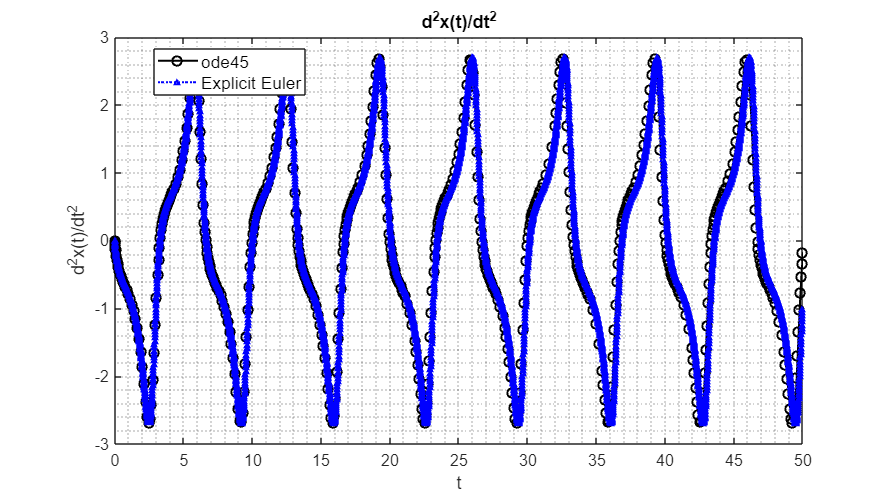

% Plot the numerical solutions for x''
plot(t2, y2(2, :), '-ok', LineWidth = 1.5, MarkerSize = 7);  % plot ode45
hold on
plot(t1, y1(2, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Explicit Euler
hold off

title('d^2x(t)/dt^2', FontSize = 15);
legend('ode45', 'Explicit Euler', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('d^2x(t)/dt^2');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

4. Let µ = 2000 and obtain a numerical solution using explicit Euler with the same stepsize used in part 2. of this exercise. What do you observe? 

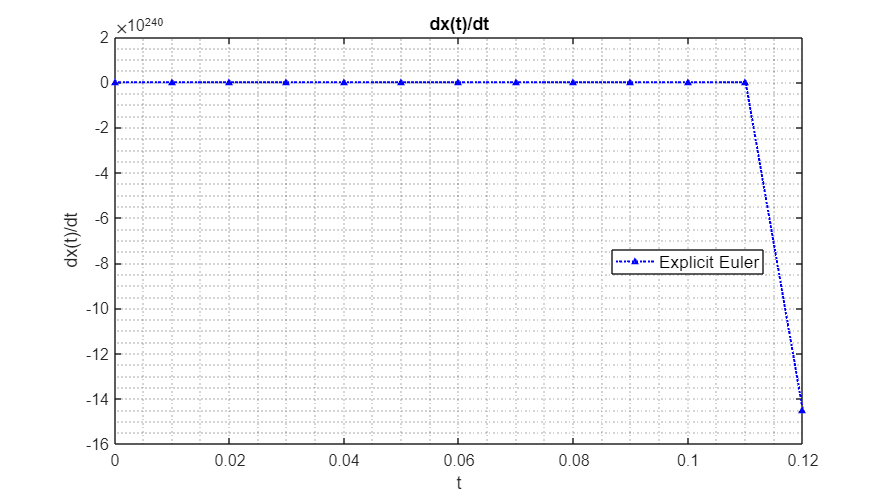

% Housekeeping
clear
clc

% Define the basic parameters
y0 = [2; 0]; % define the initial condition
t0 = 0;      % define the initial time
tf = 50;     % define the final time

h = 0.01; % define the stepsize h

Mu = 2000; % scalar parameter

% Define the function
f = @(t, y) [y(2); -y(1) + Mu * (1 - y(1) ^ 2) * y(2)];

% Compute the numerical solution
[t1, y1] = ExplicitEuler(f, t0, tf, y0, h);

% Plot the numerical solutions for x'
plot(t1, y1(1, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Explicit Euler

title('dx(t)/dt', FontSize = 15);
legend('Explicit Euler', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('dx(t)/dt');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

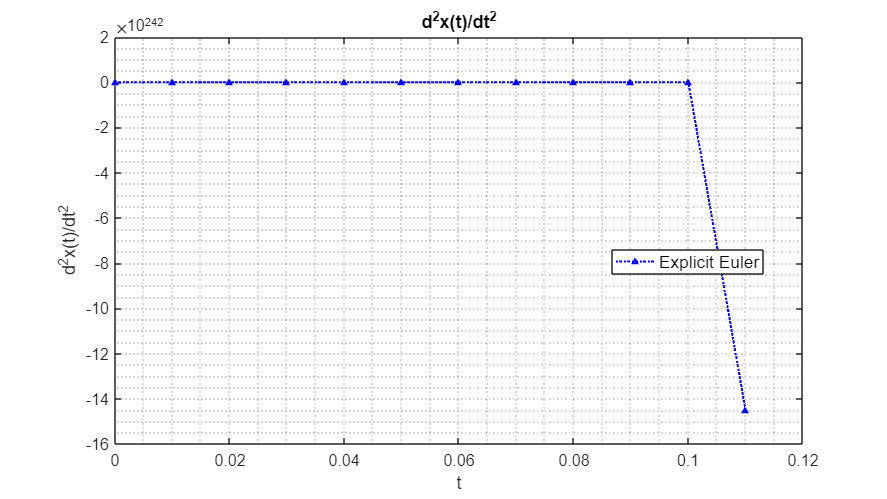

% Plot the numerical solutions for x''
plot(t1, y1(2, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot Explicit Euler

title('d^2x(t)/dt^2', FontSize = 15);
legend('Explicit Euler', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('d^2x(t)/dt^2');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

5. For µ = 2000, we wish to obtain numerical solutions using MATLAB’s built-in functions1 . 

(a) Obtain a numerical solution using “ode45” (with the default tolerance options). 

(b) Obtain a numerical solution using “ode15s” (with the default tolerance options). 

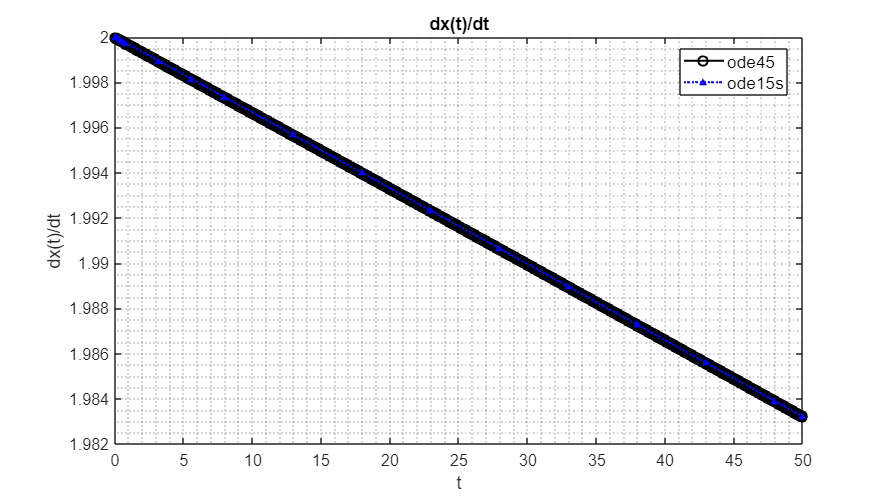

% Housekeeping
clear
clc

% Define the basic parameters
y0 = [2; 0]; % define the initial condition
t0 = 0;      % define the initial time
tf = 50;     % define the final time

Mu = 2000; % scalar parameter

% Define the function
f = @(t, y) [y(2); -y(1) + Mu * (1 - y(1) ^ 2) * y(2)];

% Using built-in function solve the numerical solutions
[t1, y1] = ode15s(f, [t0 tf], y0);
[t2, y2] = ode45(f, [t0 tf], y0);

t1 = t1';
y1 = y1';

t2 = t2';
y2 = y2';

% Plot the numerical solutions for x'
plot(t2, y2(1, :), '-ok', LineWidth = 1.5, MarkerSize = 7);  % plot ode45
hold on
plot(t1, y1(1, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot ode15s
hold off

title('dx(t)/dt', FontSize = 15);
legend('ode45', 'ode15s', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('dx(t)/dt');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

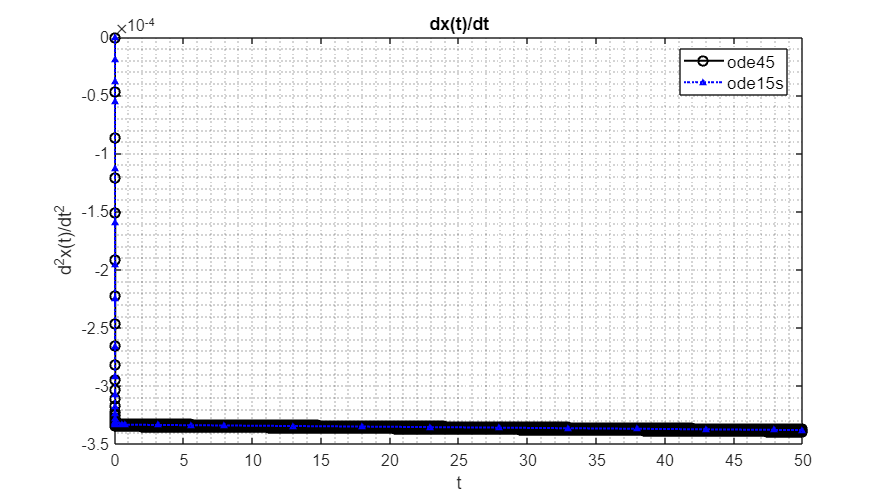

% Plot the numerical solutions for x''
plot(t2, y2(2, :), '-ok', LineWidth = 1.5, MarkerSize = 7);  % plot ode45
hold on
plot(t1, y1(2, :), ':^b', LineWidth = 1.5, MarkerSize = 3);  % plot ode15s
hold off

title('dx(t)/dt', FontSize = 15);
legend('ode45', 'ode15s', 'Location', 'Best', FontSize = 13)

xlabel('t'); 
ylabel('d^2x(t)/dt^2');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph

(c) Comment on the differences between the two. 

% ode15s is more useful for stiff systems as it choose non-uniform
% gridpoints and illustrate much less grid points

#### Exercise 4 (A two-point boundary value problem)

Consider a thin metal rod of length L = 4 in a room with an ambient temperature T¯ = 20. At one end (x = 0), the rod is in contact with a material of constant temperature T0 = 10. At the other end (x = L) the rod is in contact with a material of constant temperaturte TL = 36. The temperature distribution T(x) along the rod is described by the ODE

d^2 T / dx^2 + α(T¯ − T) = 0 ,

with boundary conditions T(0) = T0 and T(L) = TL. 

Obtain a numerical solution for this boundary value problem using the shooting method (along with your preferred numerical scheme introduced for initial value problems).

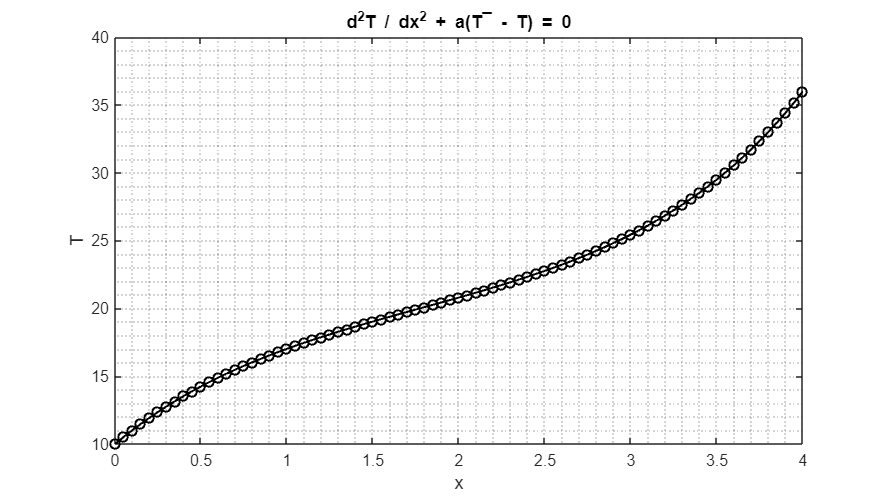

% Housekeeping
clear
clc

% Define the basic parameters
T0 = 10; % define the boundary condition
TL = 36;
x0 = 0;  % define the initial length
xL = 4;  % define the final length

Ta = 20; % ambient temperature
alp = 1;

% Define the function
f = @(x, T) [T(2); alp * (T(1) - Ta)];

% Define parameters for secant method
h = 0.05; % stepsize

tol = 1e-6; % tolerance

% Perform first guess by secant method
T2_g1 = 10; % first guess for T(2)0
T2_g2 = 50; % second guess for T(2)0

T1g = [T0; T2_g1]; % initial condition for first guess
T2g = [T0; T2_g2]; % initial condition for second guess

[x1, T1] = RungeKutta4(f, x0, xL, T1g, h); % solve ODE for first guess

error = abs(T1(1, length(x1)) - TL); % compute error

% Perform guess by secant method till in tolerance
while error > tol

    [x2, T2] = RungeKutta4(f, x0, xL, T2g, h);                         % solve ODE for nth guess

    error = abs(T2(1, length(x2)) - TL);                               % compute error

    m = (T2(2,1) - T1(2,1)) / (T2(1, length(x2)) - T1(1, length(x1))); % calculate gradient

    T2_g2 = T2(2,1) + m * (TL - (T2(1, length(x2))));                  % calculate new guess for T(2)0

    T2g = [T0; T2_g2];                                                 % define new initial condition

    x1 = x2;

    T1 = T2;

end

% Plot the numerical solutions for T''
plot(x2, T2(1, :), '-ok', LineWidth = 1.5, MarkerSize = 7);

title('d^2T / dx^2 + a(T¯ - T) = 0', FontSize = 15);

xlabel('x'); 
ylabel('T');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor; % set the grid of the graph